## Pacejka

E. Cabrol

08/01/2022

This livescript illustrates the simplest expression of Pacejka's empirical model of a tire behaviour.

It is based on the following original paper :

Bakker, E., Nyborg, L., and Pacejka, H.B. (1987). '**Tyre modelling for use in vehicle dynamics studies**'. SAE 870421

(which can be found here : [http://www.theoryinpracticeengineering.com/resources/tires/pacejka87.pdf](http://www.theoryinpracticeengineering.com/resources/tires/pacejka87.pdf))

The equation is written in two steps : 


$$Y = D\cdot \sin(C\cdot\arctan(B\cdot\phi))$$


with 


$$\phi = (1-E)\cdot X + \frac{E}{B}\ \arctan(B\cdot X)$$


It is often found under the one-line form :


$$Y = D\cdot\sin(C\cdot \arctan(B\cdot X - E(B\cdot X - \arctan(B\cdot X))$$


where

- X : longitudinal slip

- B : stiffness factor

- C : shape factor

- D : peak factor

- E : curvature factor

X, often noted *κ* (kappa) as the longitudinal slip, is expressed in % in Pacejka's paper (in more recent literature it is expressed as a ratio)

The following values are taken from Pacejka's paper, for a vertical tire load of 4 kN

clear all;
clf;
B = 0.171;
C = 1.69;
D = 4236;
E = 0.619;

Let's plot the force Y as a function of the slip ratio X :

X = linspace(0,25);
Yini = D*sin(C*atan(B*X-E*(B*X-atan(B*X))));
yh = plot(X,Yini,"Color","blue");
xlabel('longitudinal slip (%)')
ylabel('longitudinal force Fx (N)')

Let's plot the slip % for which we have the maximum force (D) :

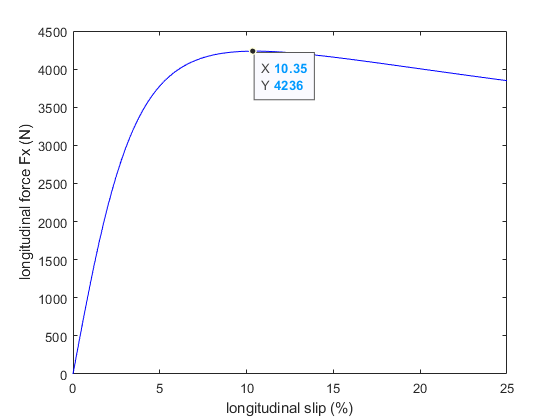

[val,idx]=max(Yini);
datatip(yh,X(idx),Yini(idx));

Now let's make the parameters vary to see their influence. Let's start by the influence of the peak factor :

clf;
[B,C,D,E] = reset;
D =4200; % peak factor (ref value = 4236)
Y = D*sin(C*atan(B*X-E*(B*X-atan(B*X))));
hold

Current plot held


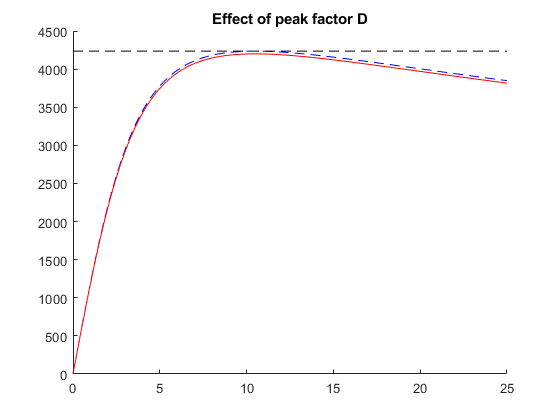

plot(X,Yini,"Color","blue","LineStyle","--")
plot(X,Y,"Color","red")
plot(X,val*ones(length(X)),"Color","black","LineStyle","--")
title('Effect of peak factor D')

Now let's see the influence of the shape factor C

clf;
[B,C,D,E] = reset;

C =1.74; % shape factor (ref value = 1.69)

Y = D*sin(C*atan(B*X-E*(B*X-atan(B*X))));
hold

Current plot held


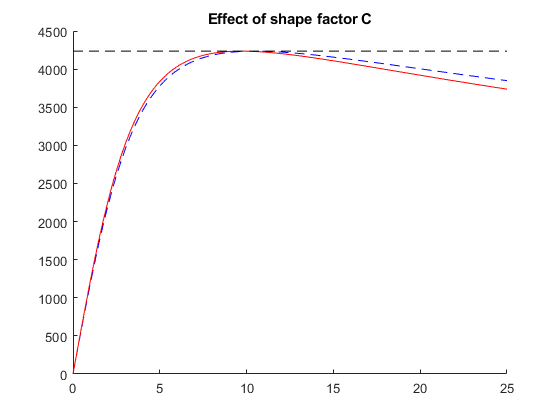

plot(X,Yini,"Color","blue","LineStyle","--")
plot(X,Y,"Color","red")
plot(X,val*ones(length(X)),"Color","black","LineStyle","--")
title('Effect of shape factor C')

Now let's see the influence of the stiffness factor B

clf;
[B,C,D,E] = reset;

B =0.2; % stiffness factor (ref value = 0.171)

Y = D*sin(C*atan(B*X-E*(B*X-atan(B*X))));
hold

Current plot held


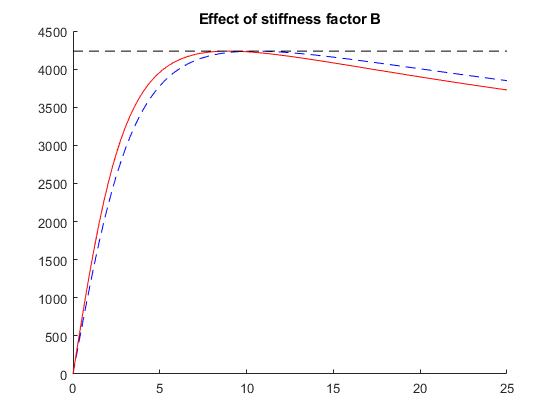

plot(X,Yini,"Color","blue","LineStyle","--")
plot(X,Y,"Color","red")
plot(X,val*ones(length(X)),"Color","black","LineStyle","--")
title('Effect of stiffness factor B')

And finally the curvature factor E :

clf;
[B,C,D,E] = reset;

E =0.6; % curvature factor (ref value = 0.619)

Y = D*sin(C*atan(B*X-E*(B*X-atan(B*X))));
hold

Current plot held


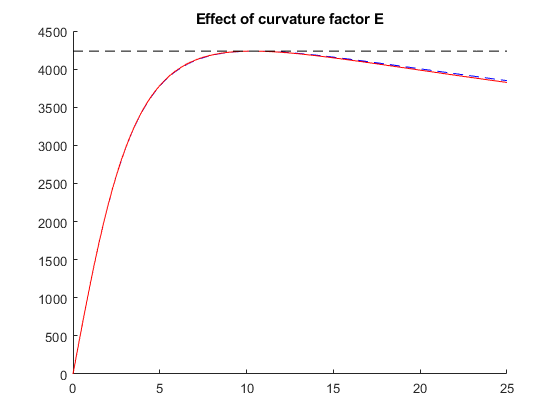

plot(X,Yini,"Color","blue","LineStyle","--")
plot(X,Y,"Color","red")
plot(X,val*ones(length(X)),"Color","black","LineStyle","--")
title('Effect of curvature factor E')

function [B,C,D,E] = reset
B = 0.171;
C = 1.69;
D = 4236;
E =  0.619;
end